# Elaborato di Calcolo Numerico: Gradiente Coniugato

Nel seguente elaborato si vogliono mostrare alcuni campi di applicazione del metodo del gradiente coniugato. Si è scelto di evidenziare come il metodo si presta per la risoluzione dei sistemi dei minimi quadrati, nell'ambito di algoritmi di Machine Learning.

#### Autori

- d'Andrea Fabio      -     M63000989

- Daniele Dario         -     M63001026

- Di Chiara Guido     -     M63000987  

- Iannucci Antimo     -     M63001040

## 1. Regressione Lineare

Dati $m$ punti $x_i \;$ed $m$ valori $y_i$ si vuole effettuare uno **smoothing **dei dati, determinando una funzione che ne approssimi l'andamento.

clear
clc

% Caricamento del dataset
% load carsmall
dataset = readtable('auto.csv');

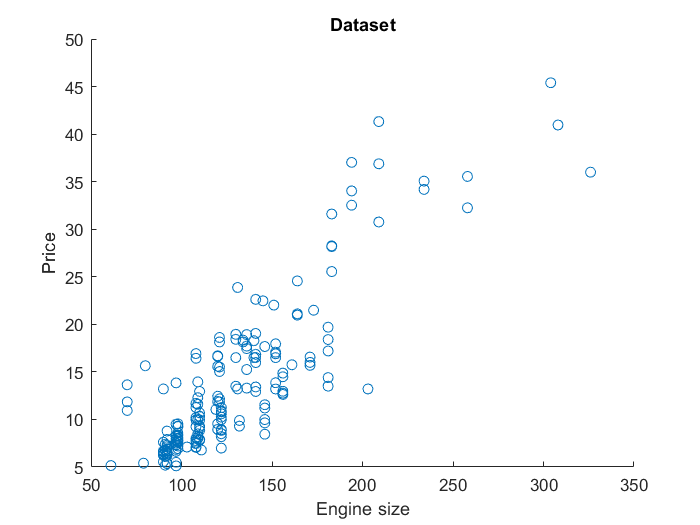


x_points = table2array(dataset(:,'engine_size'))';
y_points = str2double(table2array(dataset(:,'price')))';

% ...
x_points(isnan(x_points)) = mean(rmmissing(x_points));
y_points(isnan(y_points)) = mean(rmmissing(y_points));

% x_points = x_points/max(x_points);
y_points = y_points/1000;

scatter(x_points, y_points)
title('Dataset')
xlabel('Engine size')
ylabel('Price')

Nel caso di regressione lineare, la funzione approssimante è detta **retta dei minimi quadrati** ed è un polinomio di primo grado descritto dall'equazione:


$$p\left(x\right)=a+b\;x$$


La retta $p\left(x\right)$ è tale da minimizzare la distanza dai vari campioni, definita come:


$$\sum_{i=1}^m {\left(y_i -\left(a+b{\;x}_i \right)\right)}^2$$


Per ottenere i coefficienti $a$ e $b$ è necessario risolvere il **sistema normale**, ottenuto imponendo che le derivate parziali rispetto ad $a$ e $b$ siano nulle:


$$m\;a+\sum_{i=1}^m x_i \;b=\sum_{i=1}^m y_i$$



$$\sum_{i=1}^m x_i \;a\;+\sum_{i=1}^m {x_i }^2 \;b=\sum_{i=1}^m y_i {\;x}_i$$


La tecnica più efficiente per costruire tale sistema prevede di calcolare la matrice:

$A=\left(a_{\mathrm{ij}} \right)={x_i }^{j-1}$    con: $i=1\;,\cdots ,m;\;j=1,\cdots ,n$

La matrice ed il vettore dei termini noti del sistema sono:

$B=A^T A$  e   $d=A^T y$ 

Il sistema può quindi essere scritto come:

   
$$B\;z=d$$


m = size(x_points,2);   % numero di campioni
n_pol = 1;              % ordine del polinomio
n = n_pol+1;
    
A = zeros(m,n);
for k=1:m
    for j=1:n
        A(k,j) = x_points(k)^(j-1);
    end
end
B = A'*A;
d = A'*y_points';

...

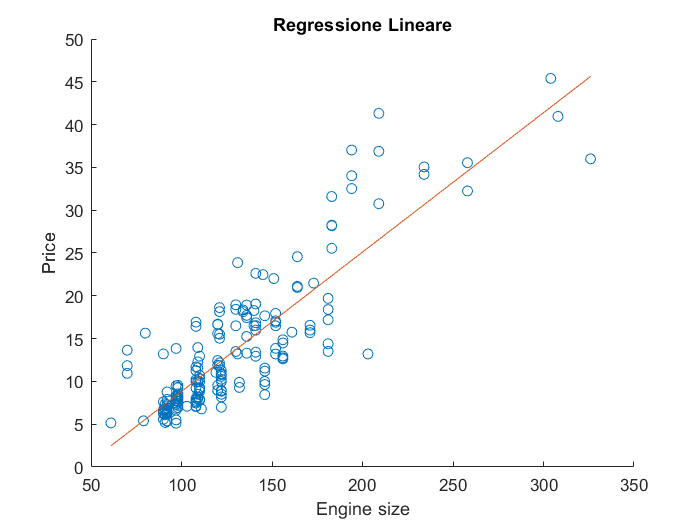

n = 1;          % ordine del polinomio
k_max = 100;    % numero massimo di iterazioni
toll = 1e-6;    % tolleranza richiesta
met = 'cg';     % metodo (gradiente o gradiente coniugato)

[p,res,iter,pvec,resvec] = poly_reg(x_points,y_points,n,k_max,toll,met);

x = min(x_points):0.1:max(x_points);
y = polyval(p,x);
scatter(x_points, y_points)
hold on
plot(x,y)
hold off
title('Regressione Lineare')
xlabel('Engine size')
ylabel('Price')

### 1.1. Analisi dei risultati

Di seguito è possibile osservare l'andamento della norma dei residui calcolati durante l'esecuzione del metodo del gradiente, al variare del numero di iterazioni.

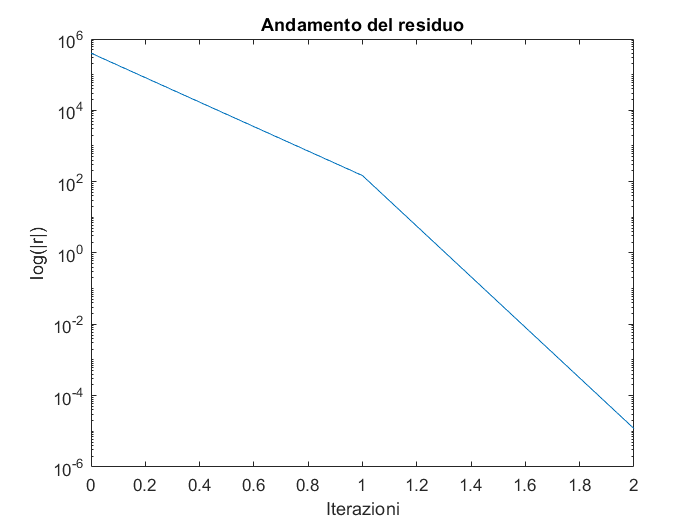

iter = 0:1:iter;
semilogy(iter,resvec)
title('Andamento del residuo')
xlabel('Iterazioni')
ylabel('log(|r|)')

Evidentemente, il metodo converge alla tolleranza specificata in sole due iterazioni. Ciò è dovuto al fatto che la matrice del sistema presenta due autovalori distinti.

eig_B = eig(B)

eig_B =      1.983842191139968e+01
     3.655565161578089e+06


... ROBA SUL CONDIZIONAMENTO

cond_B = cond(B)

cond_B =      1.842669330203725e+05


% 
% B_orig = B;
% 
% 
% [P,R,C] = equilibrate(B);
% B = R*P*B*C;
% d=R*P*d;
% 
% cond2 = cond(B)

Si può osservare come la retta dei minimi quadrati evolve durante l'esecuzione dell'algoritmo. Ad ogni iterazione l'algoritmo calcola una stima sempre più precisa della soluzione.

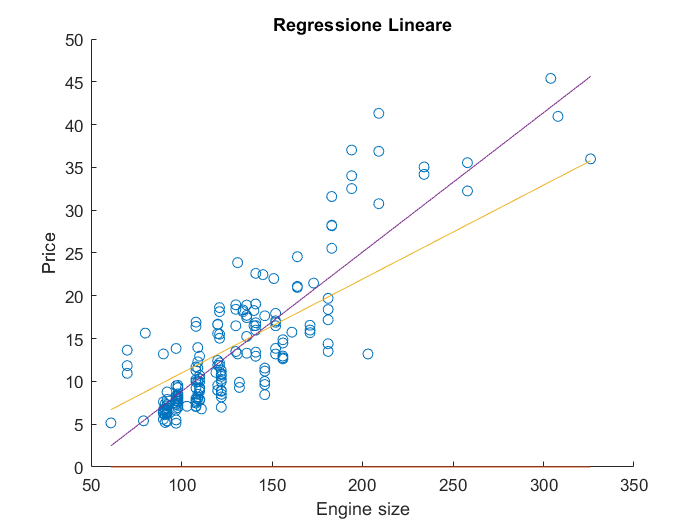

scatter(x_points, y_points)
hold on
x = min(x_points):0.1:max(x_points);
for k=1:size(pvec,2)
    y = polyval(pvec(:,k),x);
    plot(x,y)
end
hold off
title('Regressione Lineare')
xlabel('Engine size')
ylabel('Price')

Per risolvere il sistema normale, il metodo del gradiente determina il minimo della funzione di errore:


$$E\left(x\right)=\frac{1}{2}{\left(x^* -x\right)}^T A\left(x^* -x\right)$$


dove $x^*$ è la soluzione del sistema. Si può infatti dimostrare che $x^*$ coincide con il punto di minimo di tale funzione.

Non essendo noto il valore di $x^*$, per il calcolo del minimo di $E\left(x\right)$non è possibile utilizzare la sua espressione. Si considera invece la seguente funzione:


$$f\left(x\right)=\frac{1}{2}x^T A\;x-x^T b$$


Tale funzione, così come $E\left(x\right)$, è una funzione quadratica. Pur non essendo definita in segno, si può dimostrare che $f\left(x\right)$ assume valore minimo in $x^*$.

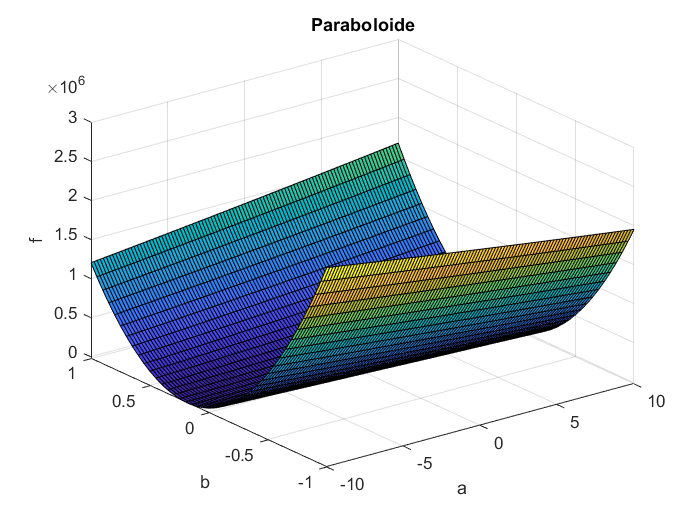

x1 = -10:0.2:10;
x2 = -1:0.05:1;
[X1,X2] = meshgrid(x1,x2);

f = (1/2)*(B(1,1)*X1.^2+(B(1,2)+B(2,1))*X1.*X2+B(2,2)*X2.^2)-(d(1)*X1+d(2)*X2);

surf(X1,X2,f)

title('Paraboloide')
xlabel('a')
ylabel('b')
zlabel('f')

Riportando le soluzioni restituite dall'algoritmo sul piano del dominio del paraboloide, è possibile osservare come avviene la ricerca del minimo. Il metodo del gradiente genera una serie di punti spostandosi lungo le direzioni A-ortogonali di massima discesa. Tali direzioni coincidono con le direzioni degli assi degli ellissi rappresentanti le curve di livello di $f\left(x\right)$.

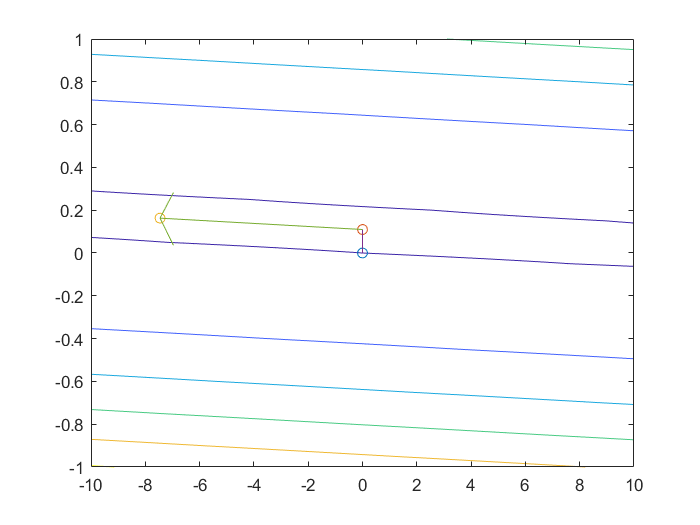

x1 = -10:0.2:10;
x2 = -1:0.05:1;
[X1,X2] = meshgrid(x1,x2);

f = (1/2)*(B(1,1)*X1.^2+(B(1,2)+B(2,1))*X1.*X2+B(2,2)*X2.^2)-(d(1)*X1+d(2)*X2);

contour(X1,X2,f);
hold on
points = flip(pvec,1);
for k=1:size(points,2)
    scatter(points(1,k),points(2,k)); 
end
for k=1:size(points,2)-1
    P1 = points(:,k);
    P2 = points(:,k+1);
    D = P2-P1;
    quiver(P1(1),P1(2),D(1),D(2),0)
end
hold off

### 1.2. Confronto con il metodo del gradiente 

Si riporta un confronto tra il metodo del gradiente coniugato ed il metodo di discesa del gradiente tradizionale. 

La principale differenza trai due metodi sta nel fatto che mentre l'ultimo si sposta nella ricerca del minimo lungo le direzioni a due a due ortogonali, il primo si sposta lungo direzioni A-ortogonali. Tale differenza si traduce in una velocità di convergenza pù elevata nel caso del gradiente coniugato, in quanto si evita di ripercorrere direzioni già percorse nel corso della ricerca.

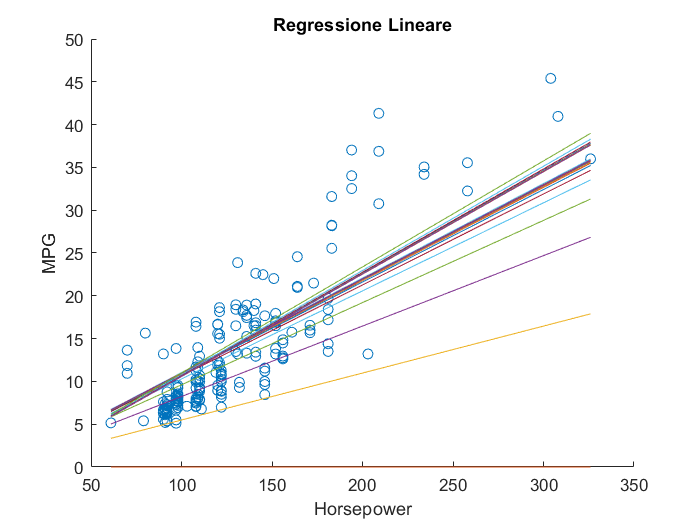

n = 1;          % ordine del polinomio
k_max = 100;    % numero massimo di iterazioni
toll = 1e-6;    % tolleranza richiesta
met = 'g';      % metodo (gradiente o gradiente coniugato)

[p_g,res_g,iter_g,pvec_g,resvec_g] = poly_reg(x_points,y_points,n,k_max,toll,met);

scatter(x_points, y_points)
hold on
x = min(x_points):0.1:max(x_points);
for k=1:size(pvec_g,2)
    y = polyval(pvec_g(:,k),x);
    plot(x,y)
end
hold off
title('Regressione Lineare')
xlabel('Horsepower')
ylabel('MPG')

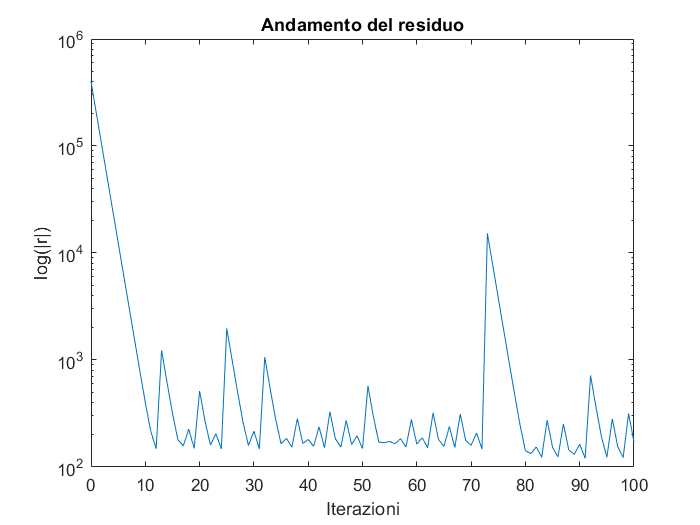

iter_g = 0:1:iter_g;
semilogy(iter_g,resvec_g)
title('Andamento del residuo')
xlabel('Iterazioni')
ylabel('log(|r|)')

## 2. Regressione Polinomiale

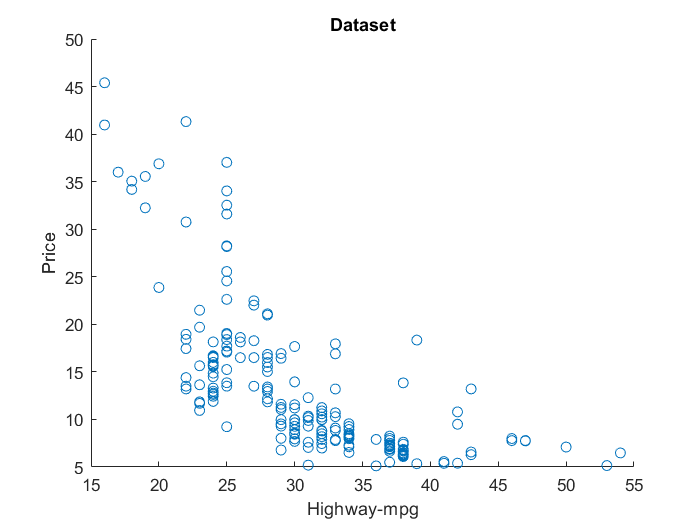

x_points = table2array(dataset(:,'highway_mpg'))';
y_points = str2double(table2array(dataset(:,'price')))';

% ...
x_points(isnan(x_points)) = mean(rmmissing(x_points));
y_points(isnan(y_points)) = mean(rmmissing(y_points));

% x_points = x_points/max(x_points);
y_points = y_points/1000;

scatter(x_points, y_points)
title('Dataset')
xlabel('Highway-mpg')
ylabel('Price')

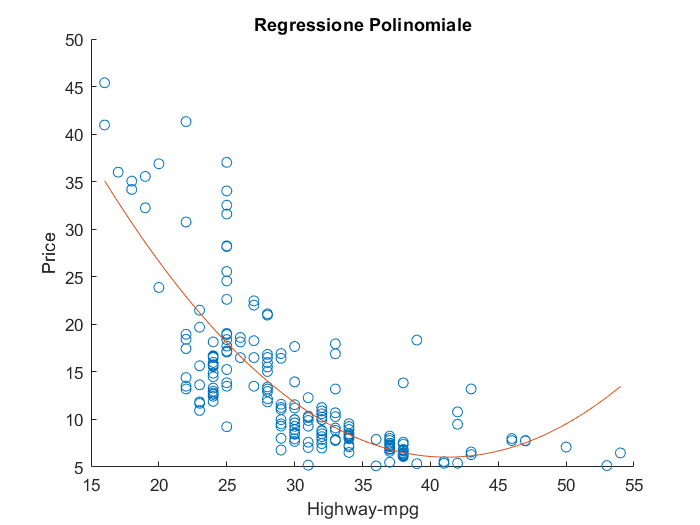

n = 2;          % ordine del polinomio
k_max = 100;    % numero massimo di iterazioni
toll = 1e-6;    % tolleranza richiesta
met = 'cg';     % metodo (gradiente o gradiente coniugato)

[p,res,iter,pvec,resvec] = poly_reg(x_points,y_points,n,k_max,toll,met);

x = min(x_points):0.1:max(x_points);
y = polyval(p,x);
scatter(x_points, y_points)
hold on
plot(x,y)
hold off
title('Regressione Polinomiale')
xlabel('Highway-mpg')
ylabel('Price')

### 2.1. Analisi dei risultati

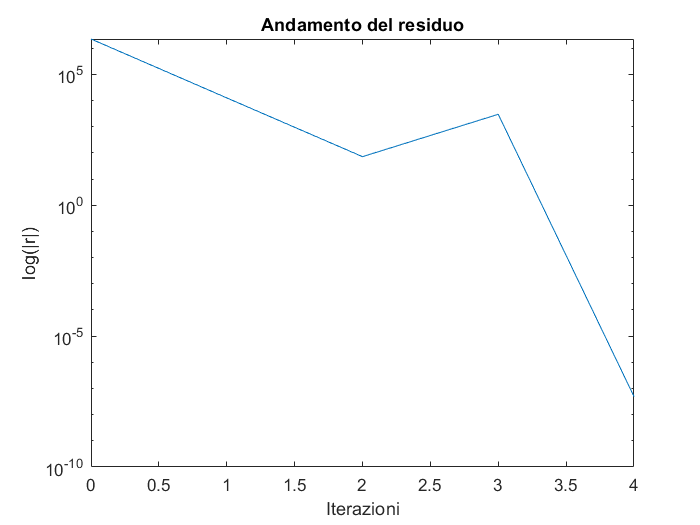

iter = 0:1:iter;
semilogy(iter,resvec)
title('Andamento del residuo')
xlabel('Iterazioni')
ylabel('log(|r|)')

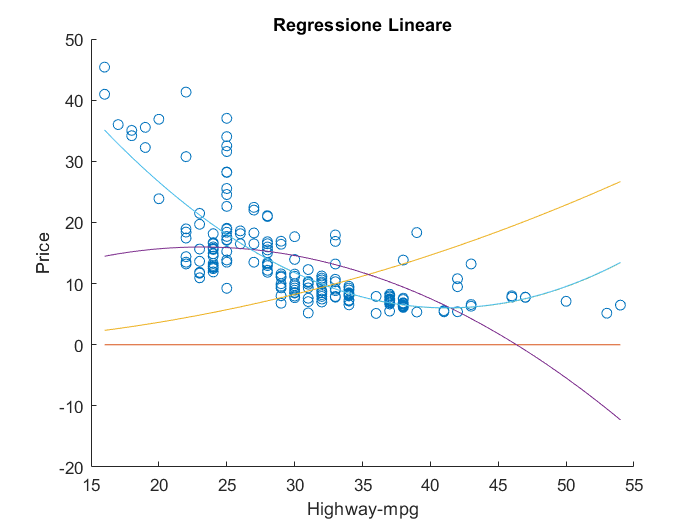

scatter(x_points, y_points)
hold on
x = min(x_points):0.1:max(x_points);
for k=1:size(pvec,2)
    y = polyval(pvec(:,k),x);
    plot(x,y)
end
hold off
title('Regressione Lineare')
xlabel('Highway-mpg')
ylabel('Price')

## 3. Regressione Lineare Multipla